# Chapter 3 #: 2, 3, 4, 5, 9, 10, 12a, 12c, 16, 20

% Problem 2
fprintf("Problem 2")

Problem 2

clear all
syms x
f1=exp(x)

$$f1 = {\mathrm{e}}^{x}$$

f2=exp(-x)

$$f2 = {\mathrm{e}}^{-x}$$

f3=exp(2*x)

$$f3 = {\mathrm{e}}^{2\,x}$$

diff([f1 f2 f3],x) %2nd row of Wronskian

$$ans = \left(\begin{array}{ccc} {\mathrm{e}}^{x} & -{\mathrm{e}}^{-x} & 2\,{\mathrm{e}}^{2\,x} \end{array}\right)$$

A=[f1,f2,f3; diff([f1,f2,f3],x); diff([f1,f2,f3],x,2)]

$$A = \left(\begin{array}{ccc} {\mathrm{e}}^{x} & {\mathrm{e}}^{-x} & {\mathrm{e}}^{2\,x}\\ {\mathrm{e}}^{x} & -{\mathrm{e}}^{-x} & 2\,{\mathrm{e}}^{2\,x}\\ {\mathrm{e}}^{x} & {\mathrm{e}}^{-x} & 4\,{\mathrm{e}}^{2\,x} \end{array}\right)$$

Wronsk=det(A)

$$Wronsk = -6\,{\mathrm{e}}^{2\,x}$$

subs(Wronsk,x,0) %This calculates W(0).

$$ans = -6$$

## Problem 3

fprintf("Problem 3")

Problem 3

clear all
syms r1 r2 z x A1 A2
r1=2+3*1i

r1 = 2.0000 + 3.0000i

real(r1)

ans = 2

imag(r1)

ans = 3

conj(r1)

ans = 2.0000 - 3.0000i

r2=1/(4+5*1i)

r2 = 0.0976 - 0.1220i

exp(3+4*1i)

ans = -13.1288 - 15.2008i

exp(pi*1i)

ans = -1.0000 + 0.0000i

z=1-3*1i

z = 1.0000 - 3.0000i

R=abs(z)

R = 3.1623

theta=angle(z)

theta = -1.2490

R.*exp(1i*theta)

ans = 1.0000 - 3.0000i

f(x)=x^4

$$f(x) = x^{4}$$

solve(f(x)-pi,x)

$$ans = \left(\begin{array}{c} -\pi^{1/4}\\ -\pi^{1/4}\,\mathrm{i}\\ \pi^{1/4}\,\mathrm{i}\\ \pi^{1/4} \end{array}\right)$$

p(x)=x^2+6*x+25

$$p(x) = x^{2}+6\,x+25$$

solve(p(x),x)

$$ans = \left(\begin{array}{c} -3-4\,\mathrm{i}\\ -3+4\,\mathrm{i} \end{array}\right)$$

subs(p(x),x,1i)

$$ans = 24+6\,\mathrm{i}$$

subs(p(x),x,2+1i)

$$ans = 40+10\,\mathrm{i}$$

[solA1, solA2]=solve((2+1i)*A1==3, A1+3*A2*1i==0)

$$solA1 = \frac{6}{5}-\frac{3}{5}\,\mathrm{i}$$

$$solA2 = \frac{1}{5}+\frac{2}{5}\,\mathrm{i}$$

## Problem 4

fprintf("Problem 4")

Problem 4

clear all
x0=1; xf=5;
y0=[2,0];
[x1,y1]=RK4(@Ch3NumExample1,[x0,xf],y0,.05);
subplot(2,1,1),plot(x1,y1(:,1))
xlabel('x'); ylabel('y')
subplot(2,1,2),plot(x1,y1(:,2))
xlabel('x'); ylabel('y')

[x1(end), y1(end,:)] %This shows the last entry of vector x1 and matrix y1. Note that we set xf=5.

ans =      0     0     0


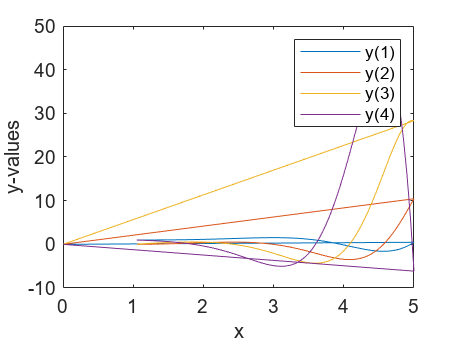

figure %calls a new blank figure window
x0=1; xf=5;
y0=[1,0,0,1];
[x2,y2]=RK4(@Ch3NumExample2,[x0,xf],y0,.05);
plot(x2,y2)
legend('y(1)','y(2)','y(3)','y(4)')
xlabel('x'); ylabel('y-values')

[x2(end), y2(end,:)]

ans =      0     0     0     0     0


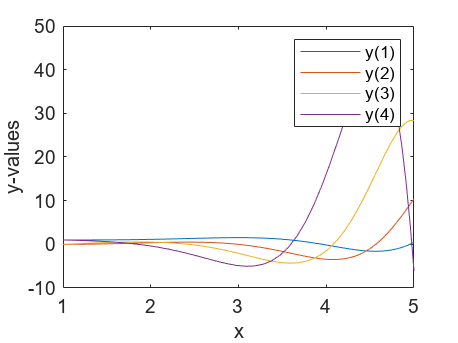

figure
[x2,y2]=ode45(@Ch3NumExample2,[x0,xf],y0); %Or use ode45.
plot(x2,y2)
legend('y(1)','y(2)','y(3)','y(4)')
xlabel('x'); ylabel('y-values')

[x2(end), y2(end,:)]

ans =     5.0000    0.4679   10.4357   28.3371   -6.0848


## Problem 5

fprintf("Problem 5")

Problem 5

clear all
%Next three lines do NOT require the Symbolic Math Toolbox
p=[1 0 3 0 1] %these are the coefficients in (v)

p =      1     0     3     0     1


%if a coefficient is 0, you must put 0 in its position
roots(p)

ans =   -0.0000 + 1.6180i
  -0.0000 - 1.6180i
  -0.0000 + 0.6180i
  -0.0000 - 0.6180i


%Now we use the Symbolic Math Toolbox:
syms x r
f(r)=r^2+3*r-4

$$f(r) = r^{2}+3\,r-4$$

solve(f(r),r)

$$ans = \left(\begin{array}{c} -4\\ 1 \end{array}\right)$$

g(r)=r^4-4*r^3+6*r^2-4*r-15

$$g(r) = r^{4}-4\,r^{3}+6\,r^{2}-4\,r-15$$

solve(g(r),r)

$$ans = \left(\begin{array}{c} -1\\ 3\\ 1-2\,\mathrm{i}\\ 1+2\,\mathrm{i} \end{array}\right)$$

h(r)=r^4+r^3-2*r-1

$$h(r) = r^{4}+r^{3}-2\,r-1$$

solve(h(r),r)

$$ans = \left(\begin{array}{c} \mathrm{root}\left(z^{4}+z^{3}-2\,z-1,z,1\right)\\ \mathrm{root}\left(z^{4}+z^{3}-2\,z-1,z,2\right)\\ \mathrm{root}\left(z^{4}+z^{3}-2\,z-1,z,3\right)\\ \mathrm{root}\left(z^{4}+z^{3}-2\,z-1,z,4\right) \end{array}\right)$$

F(r)=r^3+r-3

$$F(r) = r^{3}+r-3$$

Fsoln=solve(F(r),r)

$$Fsoln = \left(\begin{array}{c} \mathrm{root}\left(z^{3}+z-3,z,1\right)\\ \mathrm{root}\left(z^{3}+z-3,z,2\right)\\ \mathrm{root}\left(z^{3}+z-3,z,3\right) \end{array}\right)$$

Fsoln(1) % This is the first root

$$ans = \mathrm{root}\left(z^{3}+z-3,z,1\right)$$

double(Fsoln(1))

ans = 1.2134

double(Fsoln)

ans =    1.2134 + 0.0000i
  -0.6067 - 1.4506i
  -0.6067 + 1.4506i


G(r)=r^5+3*r^2-1

$$G(r) = r^{5}+3\,r^{2}-1$$

Gsoln=solve(G(r),r)

$$Gsoln = \left(\begin{array}{c} \mathrm{root}\left(z^{5}+3\,z^{2}-1,z,1\right)\\ \mathrm{root}\left(z^{5}+3\,z^{2}-1,z,2\right)\\ \mathrm{root}\left(z^{5}+3\,z^{2}-1,z,3\right)\\ \mathrm{root}\left(z^{5}+3\,z^{2}-1,z,4\right)\\ \mathrm{root}\left(z^{5}+3\,z^{2}-1,z,5\right) \end{array}\right)$$

## Problem 9

9a

fprintf("Problem 9a")

Problem 9a

clear all
syms x % {e^x, xe^x, x^2}
f1=exp(x)

$$f1 = {\mathrm{e}}^{x}$$

f2=x*exp(x)

$$f2 = x\,{\mathrm{e}}^{x}$$

f3=x.^2

$$f3 = x^{2}$$

diff([f1 f2 f3],x) %2nd row of Wronskian

$$ans = \left(\begin{array}{ccc} {\mathrm{e}}^{x} & {\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x} & 2\,x \end{array}\right)$$

A=[f1,f2,f3; diff([f1,f2,f3],x); diff([f1,f2,f3],x,2)]

$$A = \left(\begin{array}{ccc} {\mathrm{e}}^{x} & x\,{\mathrm{e}}^{x} & x^{2}\\ {\mathrm{e}}^{x} & {\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x} & 2\,x\\ {\mathrm{e}}^{x} & 2\,{\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x} & 2 \end{array}\right)$$

Wronsk=det(A)

$$Wronsk = 2\,{\mathrm{e}}^{2\,x}-4\,x\,{\mathrm{e}}^{2\,x}+x^{2}\,{\mathrm{e}}^{2\,x}$$

subs(Wronsk,x,0) %This calculates W(0).

$$ans = 2$$

9b

fprintf("Problem 9b")

Problem 9b

clear all
syms x %{sin(4x) + cos(4x), cos(4x) − sin(4x)}
f1=sin(4*x) + cos(4*x)

$$f1 = \cos\left(4\,x\right)+\sin\left(4\,x\right)$$

f2=cos(4*x) - sin(4*x)

$$f2 = \cos\left(4\,x\right)-\sin\left(4\,x\right)$$


diff([f1 f2],x) %2nd row of Wronskian

$$ans = \left(\begin{array}{cc} 4\,\cos\left(4\,x\right)-4\,\sin\left(4\,x\right) & -4\,\cos\left(4\,x\right)-4\,\sin\left(4\,x\right) \end{array}\right)$$

A=[f1,f2; diff([f1,f2],x)]

$$A = \left(\begin{array}{cc} \cos\left(4\,x\right)+\sin\left(4\,x\right) & \cos\left(4\,x\right)-\sin\left(4\,x\right)\\ 4\,\cos\left(4\,x\right)-4\,\sin\left(4\,x\right) & -4\,\cos\left(4\,x\right)-4\,\sin\left(4\,x\right) \end{array}\right)$$

Wronsk=det(A)

$$Wronsk = -8\,{\cos\left(4\,x\right)}^{2}-8\,{\sin\left(4\,x\right)}^{2}$$

subs(Wronsk,x,0) %This calculates W(0).

$$ans = -8$$

## Problem 10

10a

fprintf("Problem 10a")

Problem 10a

clear all
syms z
%(a) 2 − 3i (b) 2i (c) −1 − 5i (d) 3 + i
z=2-3i

z = 2.0000 - 3.0000i

R=abs(z)

R = 3.6056

theta=angle(z)

theta = -0.9828

R.*exp(1i*theta) %output/check

ans = 2.0000 - 3.0000i

10b

fprintf("Problem 10b")

Problem 10b

clear all
syms z
%(a) 2 − 3i (b) 2i (c) −1 − 5i (d) 3 + i
z=2i

z = 0.0000 + 2.0000i

R=abs(z)

R = 2

theta=angle(z)

theta = 1.5708

R.*exp(1i*theta) %output/check

ans = 0.0000 + 2.0000i

10c

fprintf("Problem 10c")

Problem 10c

clear all
syms z
%(a) 2 − 3i (b) 2i (c) −1 − 5i (d) 3 + i
z=-1-5i

z = -1.0000 - 5.0000i

R=abs(z)

R = 5.0990

theta=angle(z)

theta = -1.7682

R.*exp(1i*theta) %output/check

ans = -1.0000 - 5.0000i

10d

fprintf("Problem 10d")

Problem 10d

clear all
syms z
%(a) 2 − 3i (b) 2i (c) −1 − 5i (d) 3 + i
z=3+1*1i

z = 3.0000 + 1.0000i

R=abs(z)

R = 3.1623

theta=angle(z)

theta = 0.3218

R.*exp(1i*theta) %output/check

ans = 3.0000 + 1.0000i

## Problem 12a

fprintf("Problem 12a")

Problem 12a

syms z
p(z)=z.^2+4*z+8

$$p(z) = z^{2}+4\,z+8$$

subs(p(z),z,2i)

$$ans = 4+8\,\mathrm{i}$$

## Problem 12c

fprintf("Problem 12c")

Problem 12c

syms z
p(z)=z.^2+4*z+8

$$p(z) = z^{2}+4\,z+8$$

subs(p(z),z,-1+4i)

$$ans = -11+8\,\mathrm{i}$$

## Problem 16

fprintf("Problem 16")

Problem 16

clear all
x0=0; xf=20;
y0=[1,2]; %in dy order
h=0.1

h = 0.1000

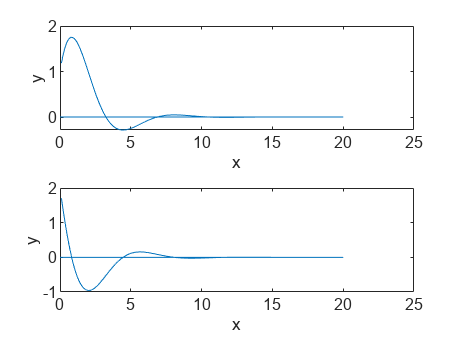

[x1,y1]=RK4(@Ch3NumExample16,[x0,xf],y0,h);
subplot(2,1,1),plot(x1,y1(:,1))
xlabel('x'); ylabel('y')
subplot(2,1,2),plot(x1,y1(:,2))
xlabel('x'); ylabel('y')

[x1(end), y1(end,:)] %This shows the last entry of vector x1 and matrix y1. Note that we set xf=20.

ans =      0     0     0


## Problem 20

20a

fprintf("Problem 20a")

Problem 20a

clear all
% (a)y''+y'+y = 0 (b) y'''+8y''+37y'+50y = 0 (c) y^(4)−4y^(3)−2y''+36y'−63y = 0
syms x r
f(r)=r^2+r+1

$$f(r) = r^{2}+r+1$$

solve(f(r),r)

$$ans = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

20b

fprintf("Problem 20b")

Problem 20b

clear all
% (a)y''+y'+y = 0 (b) y'''+8y''+37y'+50y = 0 (c) y^(4)−4y^(3)−2y''+36y'−63y = 0
syms x r
g(r)=r^3+8*r^2+37*r+50

$$g(r) = r^{3}+8\,r^{2}+37\,r+50$$

solve(g(r),r)

$$ans = \left(\begin{array}{c} -2\\ -3-4\,\mathrm{i}\\ -3+4\,\mathrm{i} \end{array}\right)$$

20c

fprintf("Problem 20c")

Problem 20c

clear all
% (a)y''+y'+y = 0 (b) y'''+8y''+37y'+50y = 0 (c) y^(4)−4y^(3)−2y''+36y'−63y = 0
syms x r
h(r)=r^4-4*r^3-2*r^2+36*r-63

$$h(r) = r^{4}-4\,r^{3}-2\,r^{2}+36\,r-63$$

solve(h(r),r)

$$ans = \left(\begin{array}{c} -3\\ 3\\ 2-\sqrt{3}\,\mathrm{i}\\ 2+\sqrt{3}\,\mathrm{i} \end{array}\right)$$

function dy= Ch3NumExample1(x,y)
%
%The original ode is 2*x*y”+x^2*y’+3*x^3*y=0
%The system of first-order equations is
%u1'=u2
%u2'=(-x/2)*u2-((3*x^2)/2)*u1
%
%We let y(1)=u1, y(2)=u2
%
dy=zeros(2,1); %dy is a column vector!
dy(1) = y(2);
dy(2) = (-1/2)*x*y(2)-(3/2)*x^2*y(1);
end
%end of function Ch3NumExample1.m

function dy= Ch3NumExample2(x,y)
%
%The original ode is y^(4)+x^2*y’+y=cos(x)
%The system of first-order equations is
%u1'=u2
%u2'=u3
%u3'=u4
%u4'=-x^2*u2-u1+cos(x)
%
%We let y(1)=u1, y(2)=u2, y(3)=u3, y(4)=u4
%
dy=zeros(4,1); %dy is a column vector!
dy(1) = y(2);
dy(2) = y(3);
dy(3) = y(4);
dy(4) = -x^2*y(2)-y(1)+cos(x);
end
%end of function Ch3NumExample2.m

function dy= Ch3NumExample16(x,y)
%
%The original ode is y''+y'+y=0

dy=zeros(2,1); %dy is a column vector!
dy(1) = y(2);
dy(2) = -y(2)-y(1);
end